# Number needed to treat (NNT)

https://www.ncbi.nlm.nih.gov/pmc/articles/PMC3083419/

The NNT is defined as the number of patients one would need to treat with the intervention in question in order to have one more success (or one less failure) than if treated in the control intervention.

1 / (event rate in treatment condition - event rate in control condition)

If NNT = 1….   1/(100% - 0%)

For example, if the response rate in the acute phase treatment of a major depressive episode is 60% in the active drug arm (EER) and 30% in the placebo arm (CER), the NNT will be calculated as 1/(0.6 - 0.3) = 3.3.

### Convert continuous d to NNT 

#### Furukawa method

- assumption of normal distributions and equal variances in the intervention and control groups

- NNT is dependent on the threshold to define response on the continuous scale.

NNT = 1 / (normcdf(d - norminv(CER)) - CER)


NNT = @(d, CER) 1 / (normcdf(d - norminv(CER)) - CER);

CER = 0:.01:1; for i = 1:length(CER), nnt_05(i) = NNT(0.5, CER(i)); end


CER is control-condition event-rate, from [0 1]. E.g., If the control effect size is 0 and an “event” is any response > 0, the CER would be 0.5, because there is a 50% chance the response would fall above 0.  If the 

#### Kraemer and Kupfer method

AUC is defined as the probability that a patient in the treatment has an outcome preferable to one in the control


AUC = normcdf(d / sqrt(2))

success rate difference (SRD):

SRD as the difference between the probability that a patient in the treatment

has an outcome preferable to one in the control and the

probability that a patient in the control has an outcome preferable

to one in the treatment

SRD = AUC - (1 - AUC) = 2 * AUC - 1


SRD = 2 .* normcdf(d / sqrt(2)) - 1


Kraemer and Kupfer NNT

KK_NNT = 1 ./ ( 2 .* normcdf(d / sqrt(2)) - 1 )


The more stringent the cutoff (e.g., % reduction in symptoms), the lower the CER (response rate in the control group), and the lower the NNT for a given effect size (d).  Conversely, 

When the response is defined at thresholds as high as 80% or 90% reduction, the CER becomes extremely low and the NNT may be considered degenerate with negative numbers and with 95% confidence intervals extending to infinity.

for a given d on a continuous outcome measure, the response rate can vary depending on the cutoff one adopts to define response.

This formula is probably wrong in the paper: It is insensitive to d and nonmonotonic.  

d = 0.5; CER = 0.06; (normcdf(d - norminv(CER))) - CER, NNT(d, CER)
d = 0.01; CER = 0.06; (normcdf(d - norminv(CER))) - CER, NNT(d, CER)


And, from tables, as CER goes down NNT goes up.  But this is not true with given formula.  And:

d = 0.17, CER = 0.61, furukawa NNT should be 15.8

from discussion: haloperidol d = 0.17

because the control event rate for 70% reduction could be as low as 6% and the corresponding NNT may be as large as 43, he/she might reason that trying olanzapine may not be worthwhile

Calculate:

D to X % of treatment group has higher scores than 95% of the control group.

## Direct simulation method

d = 0.5;
thr = norminv(.90); % zscore. 1.28.

x = randn(10000, 2);
x(:, 2) = x(:, 2) + d; % treatment effect

erate = sum(x > thr) ./ size(x, 1) % exptl and control event rates

erate =     0.0952    0.2175


nnt = 1 / abs(diff(erate))

nnt = 8.1766

#### Plot NNT as a function of d and threshold

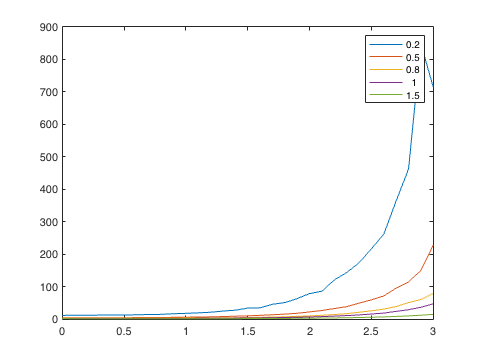


thr_vals = 0:.1:3;
d_vals = [0.2 0.5 0.8 1 1.5];

clear nnt

for j = 1:length(d_vals)

    d = d_vals(j);

    i = 1;

    for thr = thr_vals

        nnt(i, j) = get_nnt(d, thr);

        i = i + 1;

    end

end

figure; plot(thr_vals, nnt);

legendvals = cellstr(num2str(d_vals'))';
legend(legendvals)


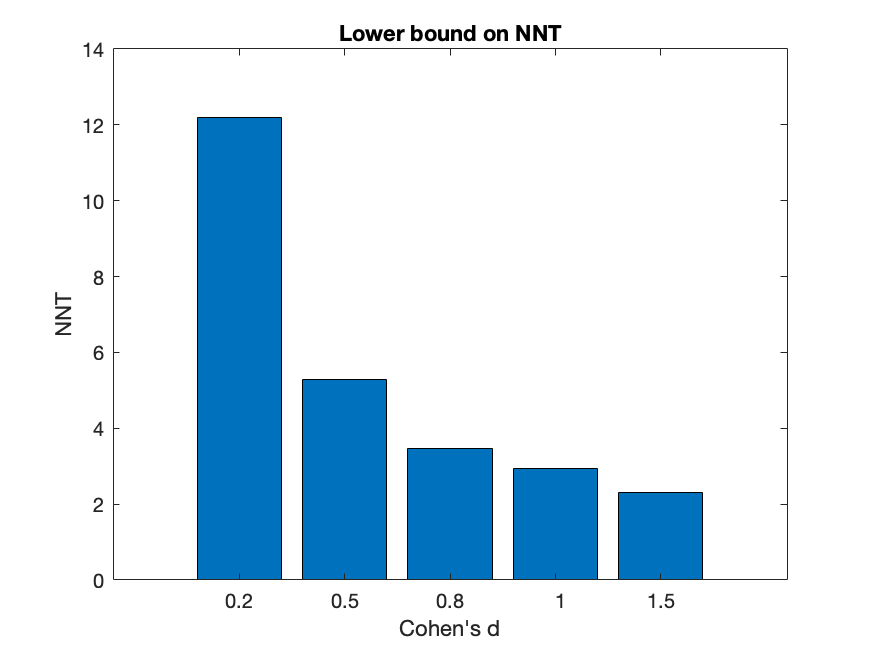

figure; bar(nnt(1, :)); set(gca, 'Xtick', 1:length(d_vals), 'XTickLabel', legendvals)
title('Lower bound on NNT')
xlabel('Cohen''s d')
ylabel('NNT')


NNT varies from about 5 to about 300 with d = 0.5, depending on how stringent the threshold is for an improvement.  

function nnt = get_nnt(d, thr)

x = randn(100000, 2);
x(:, 2) = x(:, 2) + d; % treatment effect

erate = sum(x > thr) ./ size(x, 1); % exptl and control event rates
nnt = 1 / abs(diff(erate));

end
